data = load("cust.mat")

data = struct with fields:
    cust: [93×4 table]


trainingData = data.cust

trainingData = 93×4 table
                      imageFilename                                 can                        bottle                pouch    
    __________________________________________________    ________________________    ________________________    ____________

    {'C:\Users\Vinoth\Desktop\models_samples\201.png'}    {[     321 101 182 108]}    {3×4 double            }    {6×4 double}
    {'C:\Users\Vinoth\Desktop\models_samples\202.png'}    {5×4 double            }    {[      101 46 309 399]}    {6×4 double}
    {'C:\Users\Vinoth\Desktop\models_samples\203.png'}    {3×4 double            }    {2×4 double            }    {4×4 double}
    {'C:\Users\Vinoth\Desktop\models_samples\204.png'}    {2×4 double            }    {[   848.5000 1 248 63]}    {7×4 double}
    {'C:\Users\Vinoth\Desktop\models_samples\205.png'}    {5×4 double      

trainingData.imageFilename = fullfile(trainingData.imageFilename)

trainingData = 93×4 table
                      imageFilename                                 can                        bottle                pouch    
    __________________________________________________    ________________________    ________________________    ____________

    {'C:\Users\Vinoth\Desktop\models_samples\201.png'}    {[     321 101 182 108]}    {3×4 double            }    {6×4 double}
    {'C:\Users\Vinoth\Desktop\models_samples\202.png'}    {5×4 double            }    {[      101 46 309 399]}    {6×4 double}
    {'C:\Users\Vinoth\Desktop\models_samples\203.png'}    {3×4 double            }    {2×4 double            }    {4×4 double}
    {'C:\Users\Vinoth\Desktop\models_samples\204.png'}    {2×4 double            }    {[   848.5000 1 248 63]}    {7×4 double}
    {'C:\Users\Vinoth\Desktop\models_samples\205.png'}    {5×4 double      

rng(0);
shuffledIdx = randperm(height(trainingData));
trainingData = trainingData(shuffledIdx,:);

imds = imageDatastore(trainingData.imageFilename)

imds =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Vinoth\Desktop\models_samples\232.png';
                              'C:\Users\Vinoth\Desktop\models_samples\249.png';
                              'C:\Users\Vinoth\Desktop\models_samples\222.png'
                               ... and 90 more
                              }
                     Folders: {
                              'C:\Users\Vinoth\Desktop\models_samples'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


blds = boxLabelDatastore(trainingData(:,2:end));

blds

blds =   boxLabelDatastore with properties:

    LabelData: 
               93x2 cell array
               
               { 2×4 double}    { 2×1 categorical}
               {11×4 double}    {11×1 categorical}
               { 6×4 double}    { 6×1 categorical}
               
                ... and 90 more rows
    ReadSize: 1


numclass = size(trainingData,2)-1

numclass = 3

ds = combine(imds,blds)

ds =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 boxLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]


% tbl = countEachLabel(blds)
% tbl

inputSize = [416 416 3];
numClasses = 3;
numAnchors = 9;
anchorBoxes = [
    33 55
    18 20
    23 29
    84 109
];
% Construct the layer graph
layers = [
    imageInputLayer(inputSize, 'Name', 'input')

    % First block
    convolution2dLayer(3, 16, 'Stride', 1, 'Padding', 'same', 'Name', 'conv1')
    batchNormalizationLayer('Name', 'bn1')
    reluLayer('Name', 'relu1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool1')
    
    % Second block
    convolution2dLayer(3, 32, 'Stride', 1, 'Padding', 'same', 'Name', 'conv2')
    batchNormalizationLayer('Name', 'bn2')
    reluLayer('Name', 'relu2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool2')
    
    % Third block
    convolution2dLayer(3, 64, 'Stride', 1, 'Padding', 'same', 'Name', 'conv3')
    batchNormalizationLayer('Name', 'bn3')
    reluLayer('Name', 'relu3')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool3')
    
    % Fourth block
    convolution2dLayer(3, 128, 'Stride', 1, 'Padding', 'same', 'Name', 'conv4')
    batchNormalizationLayer('Name', 'bn4')
    reluLayer('Name', 'relu4')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool4')
    
    % Fifth block
    convolution2dLayer(3, 256, 'Stride', 1, 'Padding', 'same', 'Name', 'conv5')
    batchNormalizationLayer('Name', 'bn5')
    reluLayer('Name', 'relu5')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool5')
    
    % Sixth block
    convolution2dLayer(3, 512, 'Stride', 1, 'Padding', 'same', 'Name', 'conv6')
    batchNormalizationLayer('Name', 'bn6')
    reluLayer('Name', 'relu6')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool6')
    
    % Additional layers to make up 32 layers
    convolution2dLayer(3, 1024, 'Stride', 1, 'Padding', 'same', 'Name', 'conv7')
    batchNormalizationLayer('Name', 'bn7')
    reluLayer('Name', 'relu7')
    
    convolution2dLayer(3, 1024, 'Stride', 1, 'Padding', 'same', 'Name', 'conv8')
    batchNormalizationLayer('Name', 'bn8')
    reluLayer('Name', 'relu8')
    
    convolution2dLayer(1, numAnchors*(numClasses + 5), 'Stride', 1, 'Padding', 'same', 'Name', 'conv9')
];

% Create the layer graph
lgraph = layerGraph(layers);

lgraph = yolov2Layers(inputSize,numclass,anchorBoxes,lgraph,'relu4');
lgraph.Layers

options = trainingOptions('sgdm',...
          'InitialLearnRate',0.001,...
          'Verbose',true,...
          'MiniBatchSize',16,...
          'MaxEpochs',150,...
          'Shuffle','never',...
          'VerboseFrequency',30,...
          'CheckpointPath',tempdir);
tempdir

ans = 'C:\Users\Vinoth\AppData\Local\Temp\'

[detector,info] = trainYOLOv2ObjectDetector(ds,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* can
* bottle
* pouch

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |        10.21 |        104.1 |          0.0010 |
|       6 |          30 |       00:01:39 |         1.39 |          1.9 |          0.0010 |
|      12 |          60 |       00:03:16 |         1.19 |          1.4 |          0.0010 |
|      18 |          90 |       00:06:18 |         1.04 |          1.1 |          0.0010 |
|      24 |         120 |       00:09:02 

save("Detector.mat","detector")

detector

detector =   yolov2ObjectDetector with properties:

            ModelName: 'can'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [416 416]
          AnchorBoxes: [4×2 double]
           ClassNames: [can    bottle    pouch]


img = imread("sample.png");
[bboxes,scores,labels] = detect(detector,img)

bboxes =    331     1    68    34
   160    19    53    49
   387    21    89    48
    83     4    45   104
   256    91    50    52
   181   184    75    44
   126   168    51    87


scores = 7×1 single column vector
    0.5034
    0.7899
    0.5916
    0.6291
    0.8447
    0.7960
    0.5839


labels = 7×1 categorical array
     can 
     can 
     bottle 
     bottle 
     bottle 
     can 
     bottle 


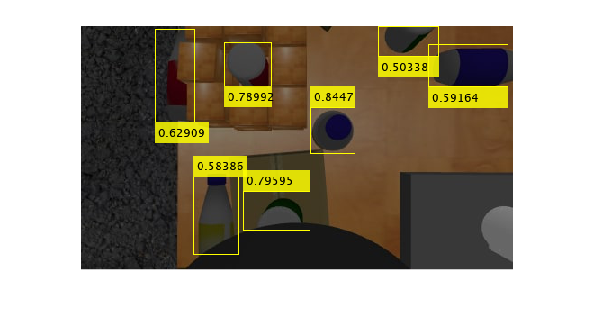

if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',bboxes,scores);
end
figure
imshow(img)